clc
clear
close all 

b = 50;
m = 1000;
tau_p = m/b;

num_p = 1;
den_p = b*[tau_p 1];

P = tf(num_p,den_p)


P =
 
       1
  -----------
  1000 s + 50
 
Continuous-time transfer function.
Model Properties



% t = 0:0.1:1000;
step(500*P);
grid on;
hold on

Tr = 20; % Tempo di salita [s].
Wc = 5/Tr; % Omega critica [rad/s].
Ki = Wc*b; % Ki.
Kp = tau_p*Ki % Kp.

Kp = 250

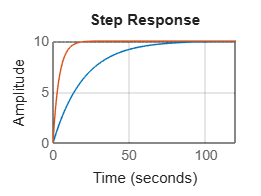


C = pid(Kp,Ki); % Controllore PI.

L = C*P; % Sistema ad anello aperto.

W = feedback(L,1); % Sistema ad anello chiuso.

% t = 0:0.1:200;
step(10*W);
grid on;
hold off

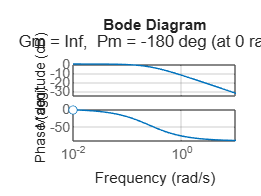


margin(W);
grid on;

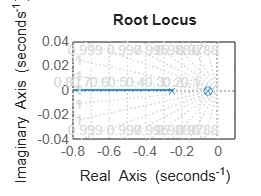


rlocus(W)
grid on;


pole(W)

ans =    -0.2500
   -0.0500


Space State Eq.

m = 2;
b = 0.5;
F = 1;

% A = [0 1;-b/m 0];
% B = [0 1/m]';
% C = [0 1];
% D = [0];

A = -b/m;
B = 1/m;
C = 1;
D = 0;

% Converti in funzione di trasferimento
% [num, den] = ss2tf(A, B, C, D);

% Crea l'oggetto funzione di trasferimento
% G = tf(num, den);

sys = ss(A,B,C,D)


sys =
 
  A = 
          x1
   x1  -0.25
 
  B = 
        u1
   x1  0.5
 
  C = 
       x1
   y1   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Properties



Z = tf(sys)


Z =
 
    0.5
  --------
  s + 0.25
 
Continuous-time transfer function.
Model Properties



num = 1;
den = [m b];

K = tf(num,den)


K =
 
      1
  ---------
  2 s + 0.5
 
Continuous-time transfer function.
Model Properties


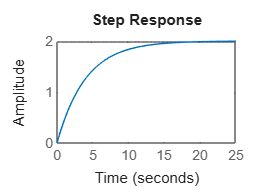


% step(Z)
% hold on
step(K)